sigma = 10;
b = 8/3;
r = 28;

P = [sigma, b, r];
IC1 = [0;1;0];
IC2 = [0;1+eps;0];

t = linspace(0,60,1e8);
load_system('lorenz.slx')

x0 = IC1

x0 =      0
     1
     0


param = 'x0, P'

param = 'x0, P'

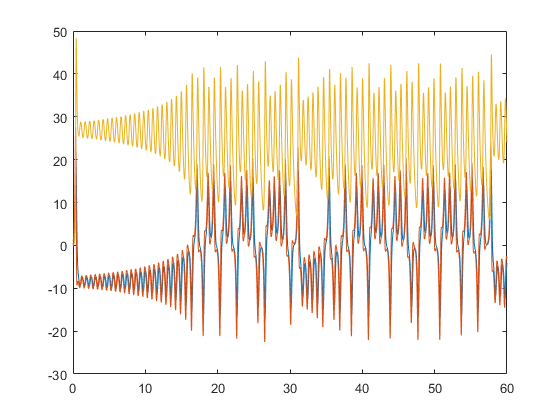

set_param('lorenz/S-Function','Parameters',param);
simout = sim('lorenz.slx','AbsTol','1e-8','StopTime','60');

figure(1)
t_a = simout.tout;
x_a = simout.simout.Data;
plot(t_a,x_a)

x0 = IC2

x0 =          0
    1.0000
         0


param = 'x0, P'

param = 'x0, P'

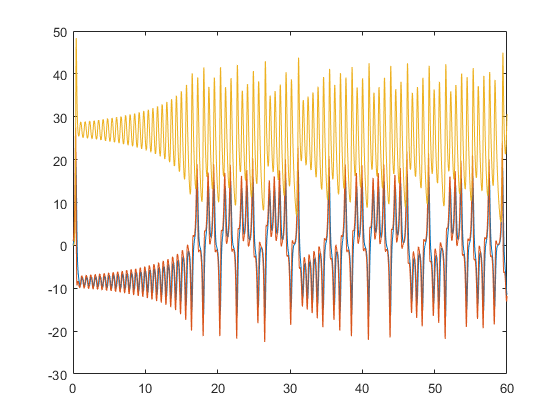

set_param('lorenz/S-Function','Parameters',param);
simout = sim('lorenz.slx','AbsTol','1e-8','StopTime','60');

figure(2)
t_b = simout.tout;
x_b = simout.simout.Data;
plot(t_b,x_b)

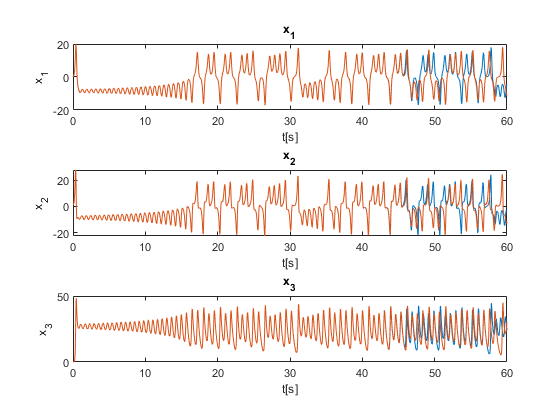

figure
subplot(3,1,1)
plot(t_a,x_a(:,1))
hold on;
plot(t_b,x_b(:,1))
title('x_1')
xlabel('t[s]')
ylabel('x_1')

subplot(3,1,2)
plot(t_a,x_a(:,2))
hold on;
plot(t_b,x_b(:,2))
title('x_2')
xlabel('t[s]')
ylabel('x_2')

subplot(3,1,3)
plot(t_a,x_a(:,3))
hold on;
plot(t_b,x_b(:,3))
title('x_3')
xlabel('t[s]')
ylabel('x_3')